# Stability Analysis of Drone Controls

Control stability analysis is a critical process in ensuring that a control system performs reliably and efficiently. This example shows how to analyze and validate the stability of aircraft control systems.

Copyright 2025 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('EVTOLDesignOverview.html')).

## Introduction

Open the Controls subsystem.

open_system('EVTOLTiltrotor/Controls')

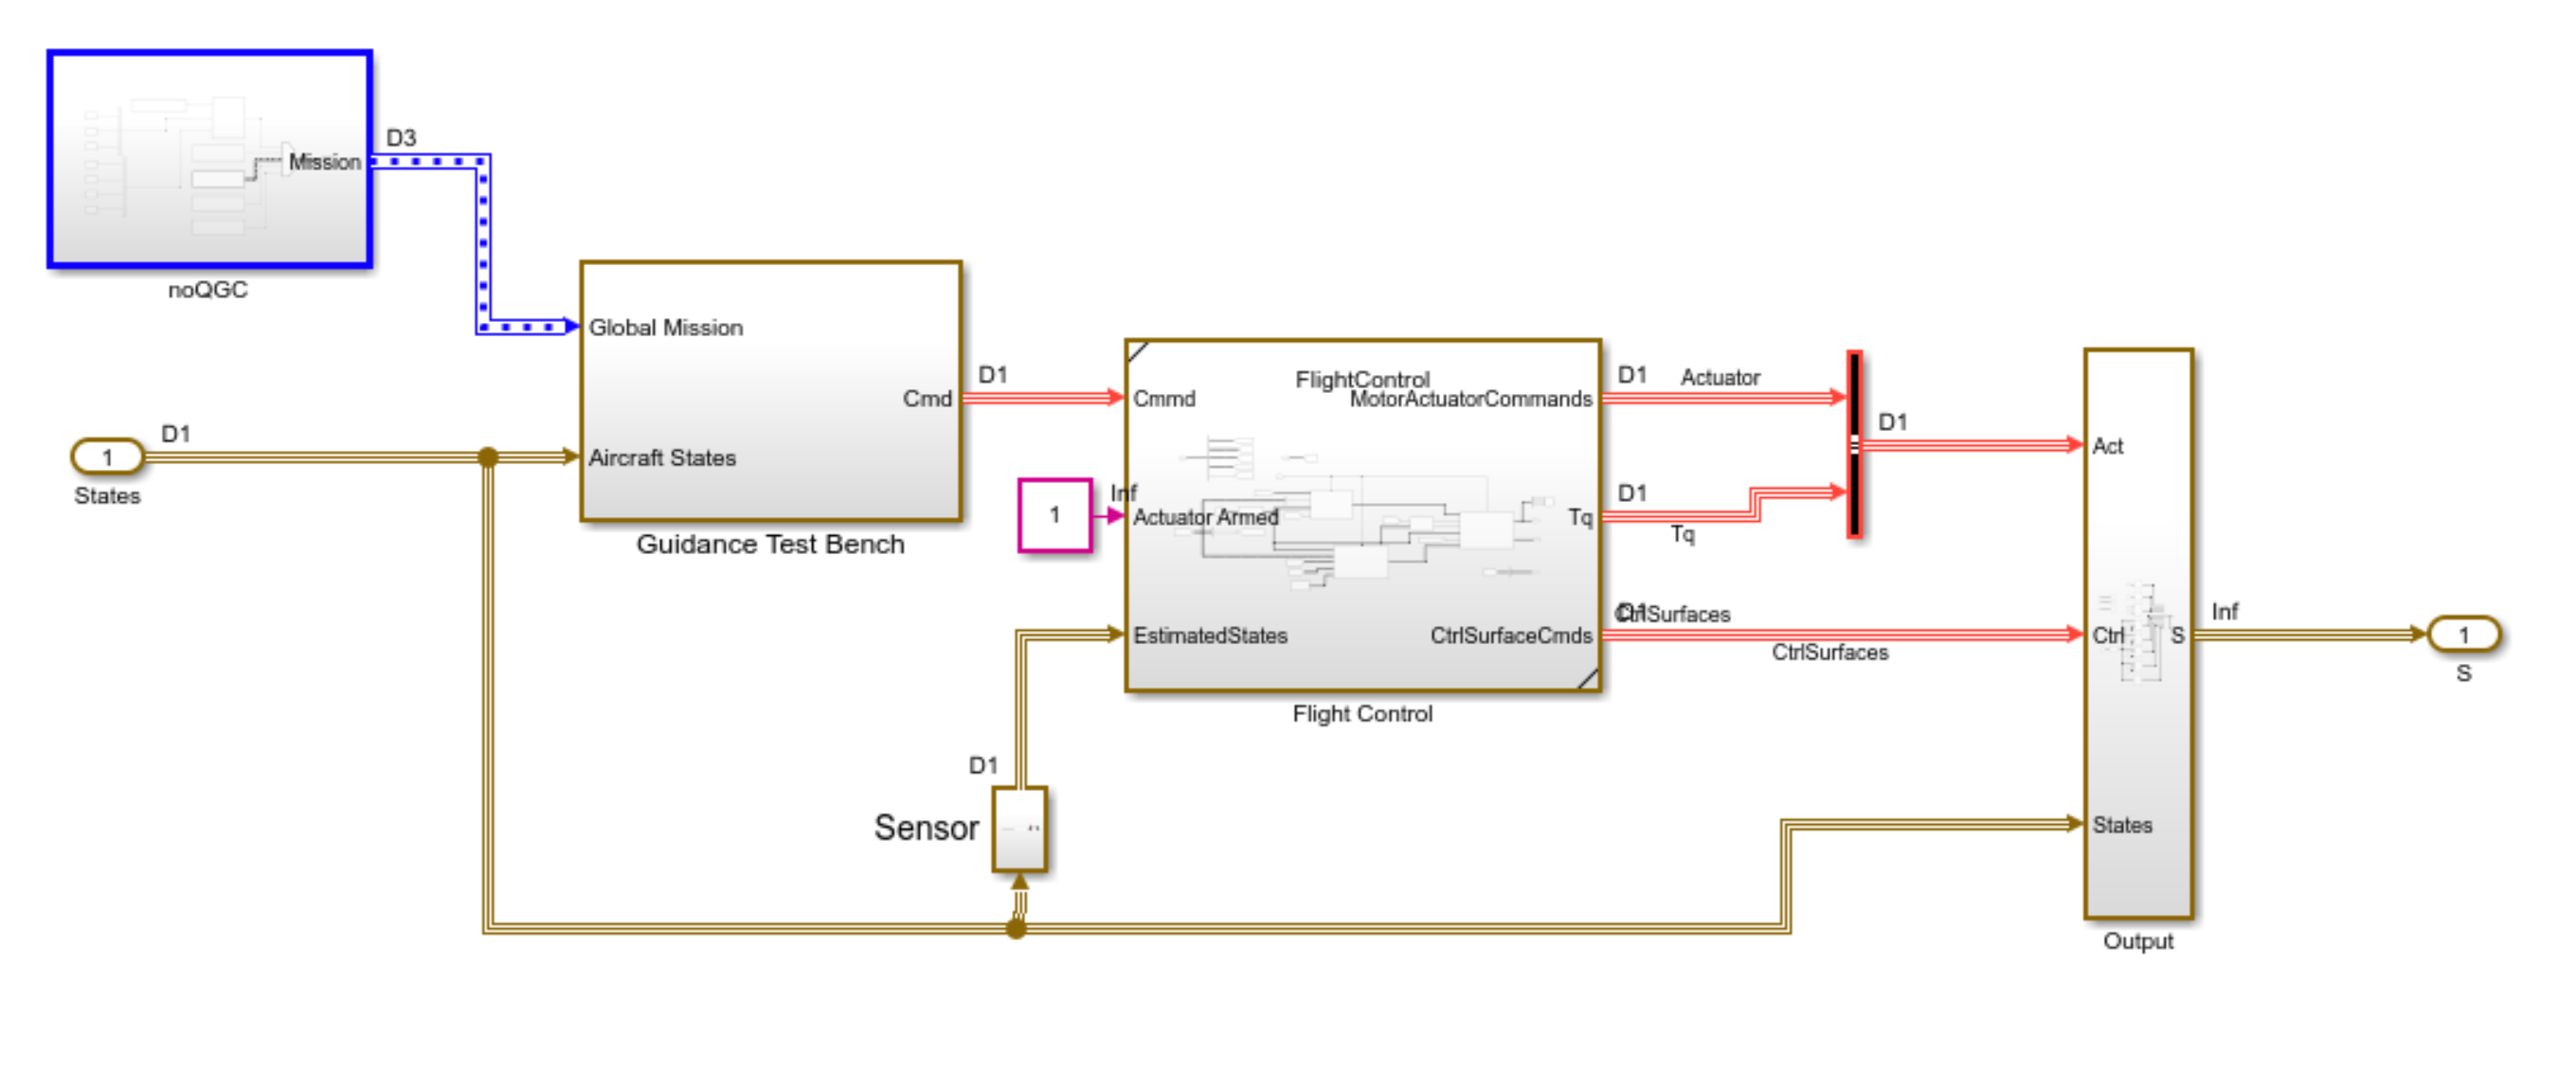

The Controls subsystem contains these subsystems:

- Ground Control Station – Contains a customized mission and sends the next state for the unmanned aerial vehicle (UAV) mission to enable the vertical takeoff and landing (VTOL) UAV to execute a set of maneuvers.

- Guidance Test Bench – Allows switching between a manual-control test bench and a guidance test bench. The guidance test bench consists of guidance logic you can use to architect specific missions and test control robustness.

- Flight Control – Controls the VTOL aircraft.

For more information about the control architecture, see the  [Tune Control Design for VTOL UAV in Hover Configuration](https://www.mathworks.com/help/uav/ug/tune-control-design-for-uav-in-hover.html)

Open the Flight Control subsystem.

open_system('EVTOLTiltrotor/Controls/Flight Control')

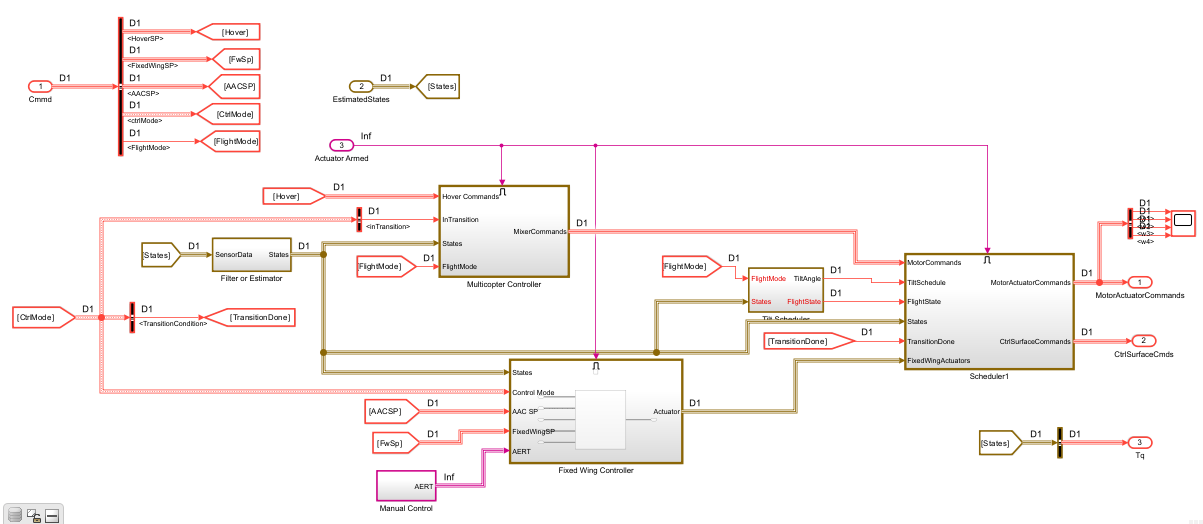

The control system blends fixed-wing and hover control. You can modify the tilt-transition controller in the Tilt Scheduler subsystem to tilt the front rotors while the VTOL aircraft is in the transition or back-transition flight modes. You can use the Scheduler subsystem to customize the control mixer for the four different flight modes. 

## Hover Control Tuning

In the hover configuration, the aircraft tilts the front two rotors to achieve forward and backward motion. All four motors are active to achieve lateral motion.

- Roll Control – Rolls the aircraft similar to a multicopter.

- Pitch Control – Stabilizes the pitch at 0 degrees to minimize aerodynamic effects.

- Yaw Control – Differentially tilts the front rotors.

Open the Multicopter Controller subsystem.

open_system('EVTOLTiltrotor/Controls/Flight Control/Multicopter Controller')

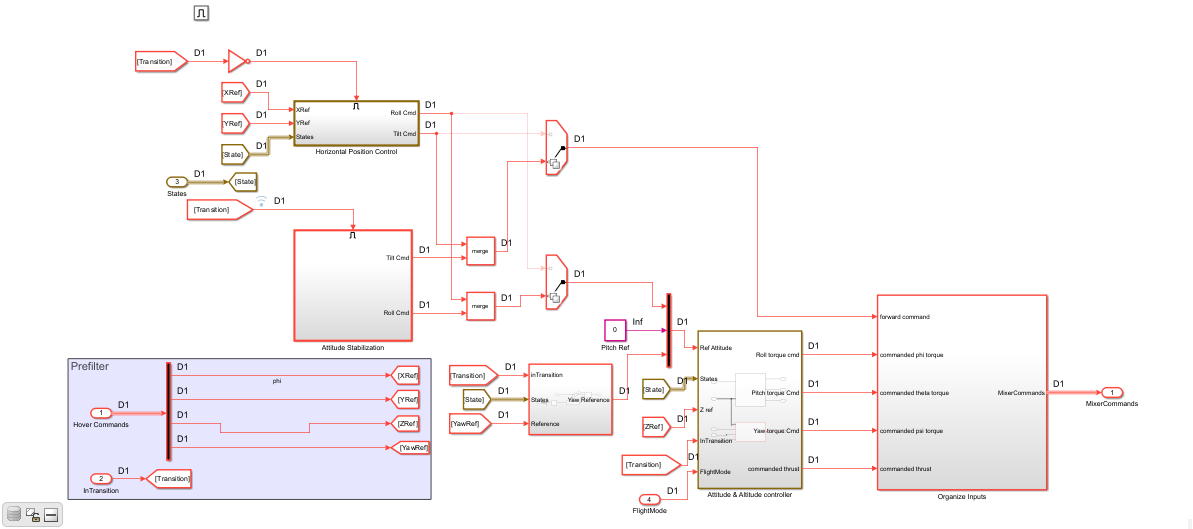

There are six independent control variables available for controlling the aircraft in hover mode: four motor speeds and two tilt angles for the front two motors.

- Altitude Control adjusts the speed of the four motors.

- Altitude Control (Yaw Control) controls yaw through differential vectored thrust from the two front motors. 

- Horizontal Position Controlter controls forward movement through collective vectored thrust from the two front motors. For forward movement, both motors tilt forward.

Set the aircraft to use hover configuration with manual controls.

SetupHoverConfiguration;
SetupHoverManual;

Reset the multicopter commands to the initial condition so you can linearize the model.

set_param([mdl '/Manual Control Dashboard/Slider1'],'Value','50');
set_param([mdl '/Manual Control Dashboard/Slider2'],'Value','0');
set_param([mdl '/Manual Control Dashboard/Slider3'],'Value','0');
% TestMode to 0 - Manual Mode
TestMode = 0;
% AutotuningMission true - Tune Controller
AutotuningMission = true;
% Disable Sensors
SensorType = 0;

To tune the hover mode controls, in the MATLAB® Control Window enter `exampleHelperAutomatedHoverControlTuning`*. *You can instead load the tuned parameters from the `tunedHoverGains_BW50` MAT file.

% load HoverControlTuning;
exampleHelperAutomatedHoverControlTuning;

## Stability Analysis of Multicopter Control

### Bode Plot

Plot bode plot for multicopter controls.

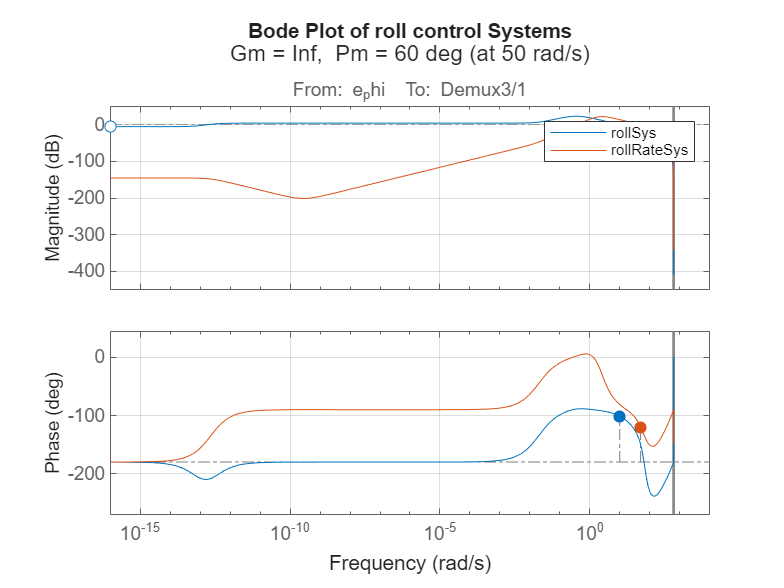

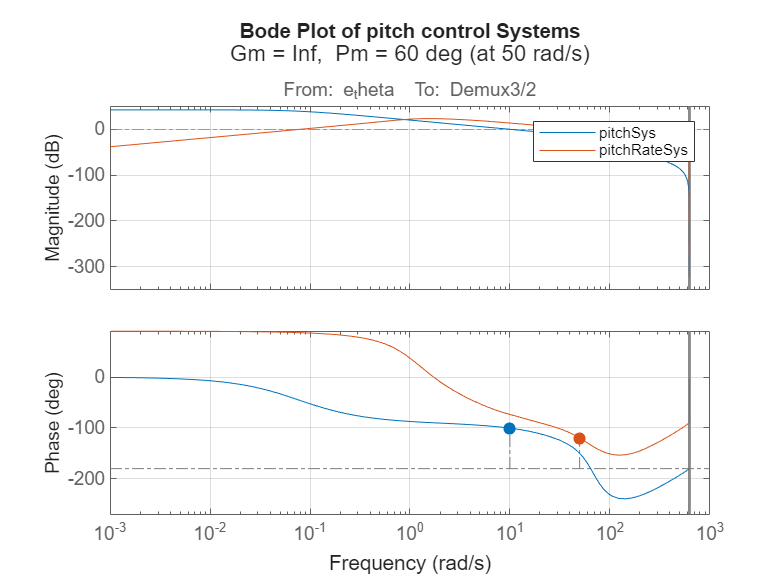

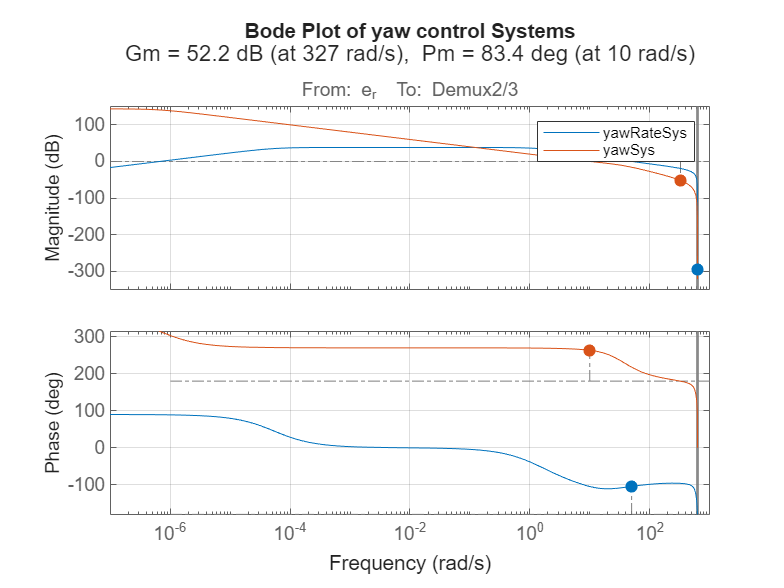

bodePlotHoverControl;

### Nichols Plot

Nichols plot for multicopter control.

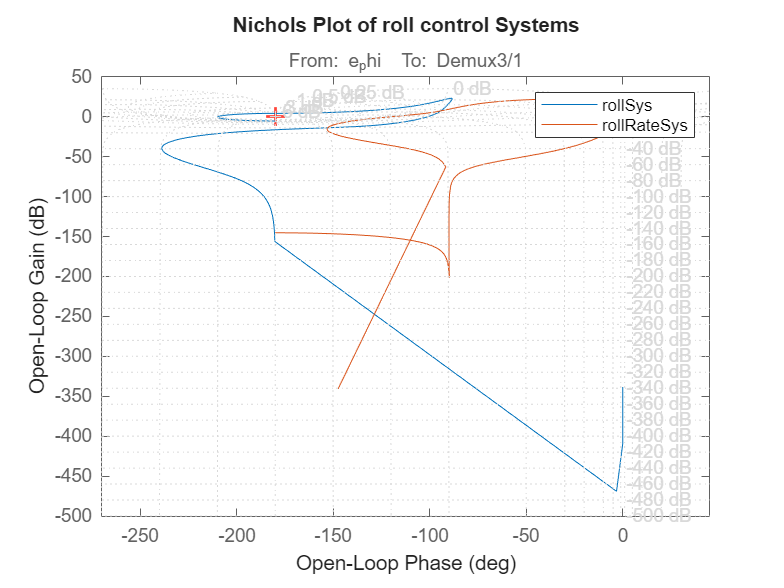

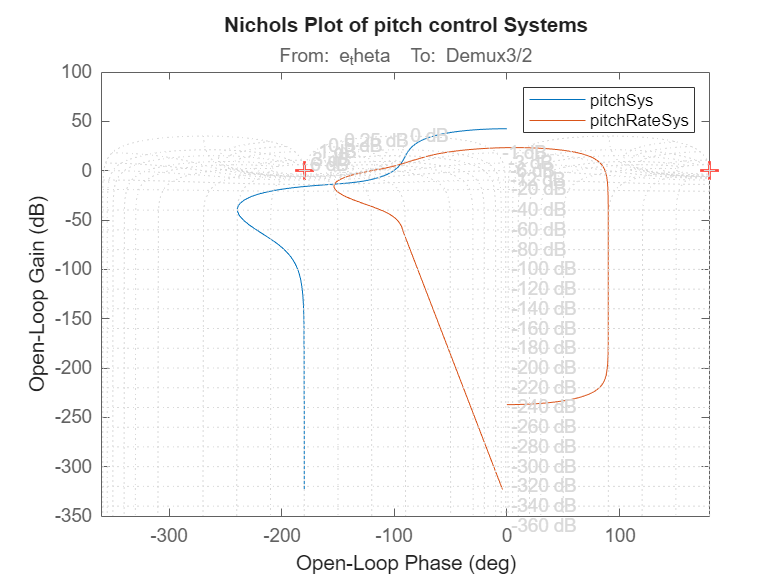

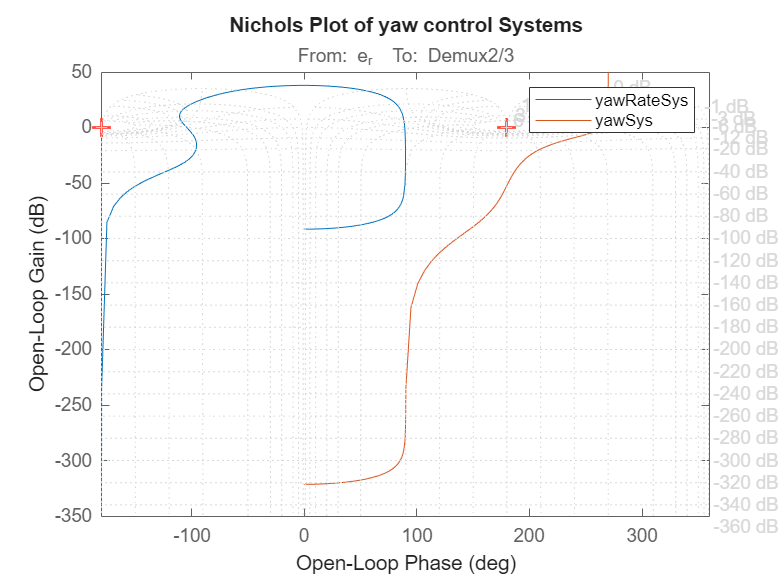

nicholsPlotHoverControl

Both the bode and nichols plot show that the attitude controller are stable and robust with high gain and phase margins.

## **References**

[1] N., Pavan. (2020). “Design of Tiltrotor VTOL and Development of Simulink Environment for Flight Simulations.” Master's Thesis, Indian Institute of Technology Madras, 2020 [here](https://www.researchgate.net/profile/Pavan-N/publication/351154528_Design_of_Tiltrotor_VTOL_and_Development_of_Simulink_Environment_for_Flight_Simulations/links/608ab0eba6fdccaebdf77bc8/Design-of-Tiltrotor-VTOL-and-Development-of-Simulink-Environment-for-Flight-Simulations.pdf).